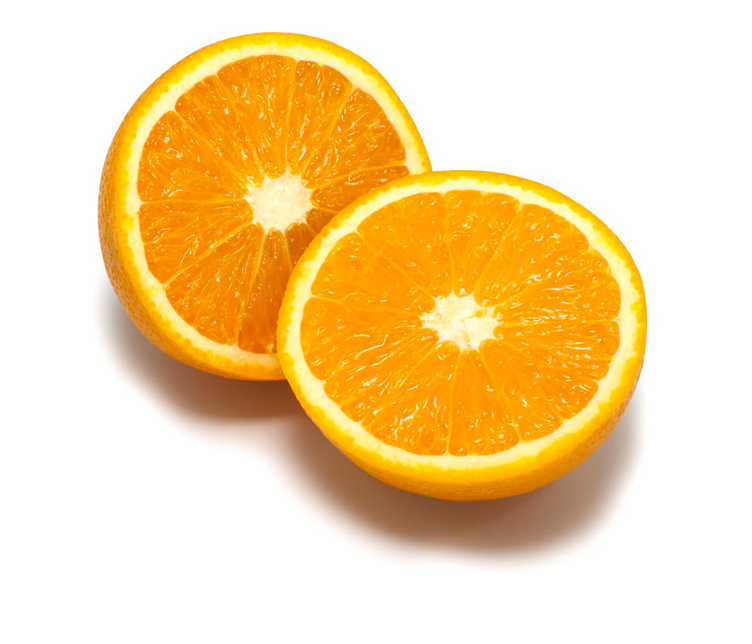

K = 8;               % number of clusters used
L = 6;              % number of iterations
seed = 20;           % seed used for random initialization
scale_factor = 1.0;  % image downscale factor
image_sigma = 1.0;   % image preblurring scale

I = imread('orange.jpg');
imshow(I);

I = imresize(I, scale_factor);
Iback = I;
d = 2*ceil(image_sigma*2) + 1;
h = fspecial('gaussian', [d d], image_sigma);
I = imfilter(I, h);

% [ segm, centers ] = kmeans_segm(I, K, L, seed);
% disp(centers);
% Inew = mean_segments(Iback, segm);
% I = overlay_bounds(Iback, segm);
% imshow(Inew);
% imshow(I);

% Q2
prev_centers = [];
for K = 2:10
    converged = false;
    for L = 1:50
        [ segm, centers ] = kmeans_segm(I, K, L, 'default');
        
        if L > 1
            largest_diff = max(abs(centers - prev_centers),[],'all');
            if largest_diff < 0.5
                converged = true;
                break
            end
        end
        prev_centers = centers;
    end
    if converged == true
        disp(sprintf("K = %i converged at L = %i", K, L));
    end
end

K = 2 converged at L = 2
K = 3 converged at L = 4
K = 4 converged at L = 4
K = 5 converged at L = 8
K = 6 converged at L = 8


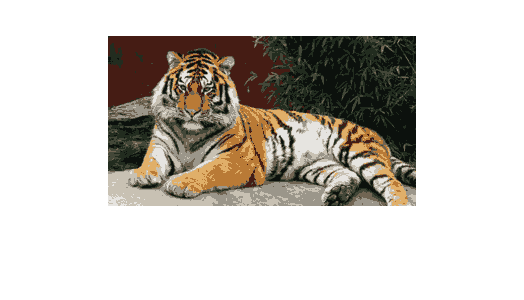

% Q3
K = 10;
L = 20;
[ segm, centers ] = kmeans_segm(I, K, L);
Inew = mean_segments(Iback, segm);
Ibounds = overlay_bounds(Iback, segm);
imshow(Inew);

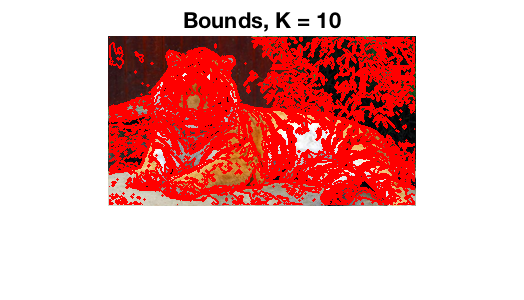

imshow(Ibounds);
title(sprintf("Bounds, K = %i", K));

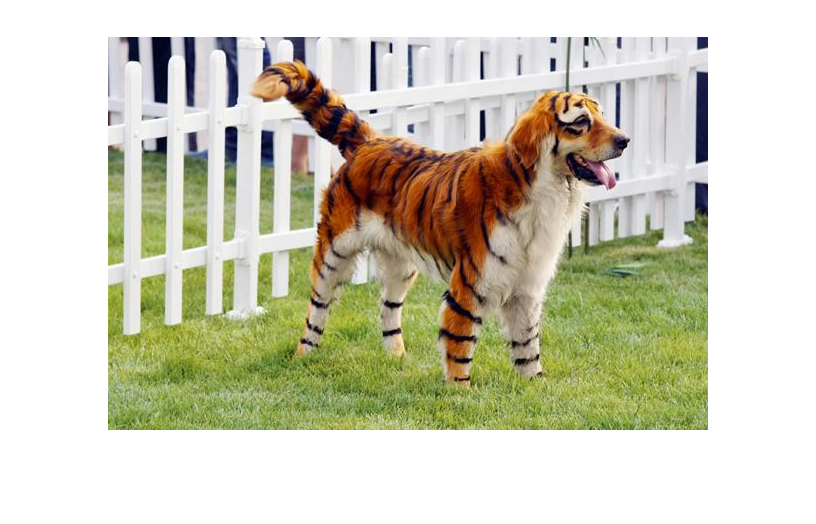

% Q4
K = 8;               % number of clusters used
L = 20;              % number of iterations
seed = 20;           % seed used for random initialization
scale_factor = 1.0;  % image downscale factor
image_sigma = 3.0;   % image preblurring scale

I = imread('tiger3.jpg');
imshow(I);

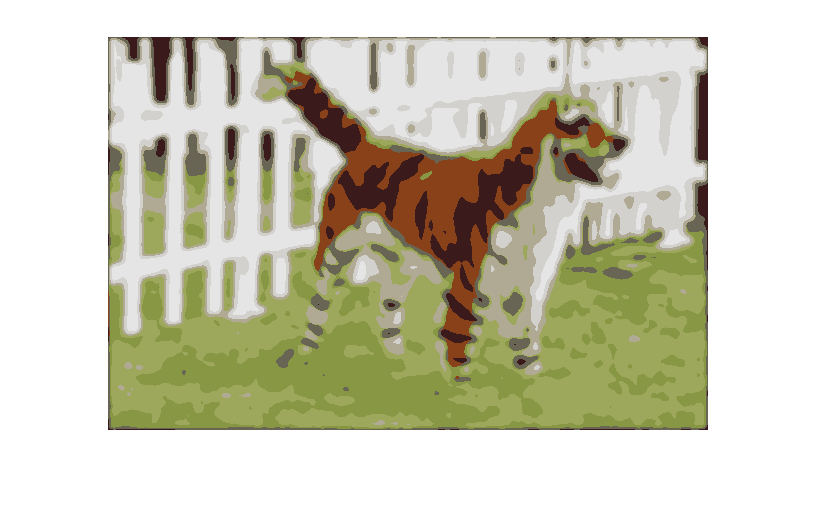

I = imresize(I, scale_factor);
Iback = I;
d = 2*ceil(image_sigma*2) + 1;
h = fspecial('gaussian', [d d], image_sigma);
I = imfilter(I, h);

[ segm, centers ] = kmeans_segm(I, K, L);
Inew = mean_segments(Iback, segm);
Ibounds = overlay_bounds(Iback, segm);
imshow(Inew);

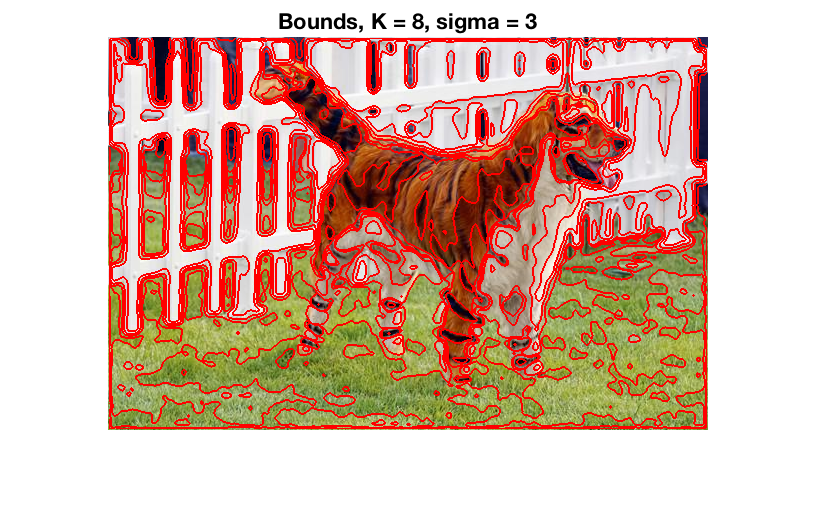

imshow(Ibounds);
title(sprintf("Bounds, K = %i, sigma = 3", K));

% Q5
scale_factor = 0.5;       % image downscale factor
spatial_bandwidth = 9.0;  % spatial bandwidth
colour_bandwidth = 4.0;   % colour bandwidth
num_iterations = 40;      % number of mean-shift iterations
image_sigma = 1.0;        % image preblurring scale

I = imread('tiger3.jpg');
I = imresize(I, scale_factor);
Iback = I;
d = 2*ceil(image_sigma*2) + 1;
h = fspecial('gaussian', [d d], image_sigma);
I = imfilter(I, h);

segm = mean_shift_segm(I, spatial_bandwidth, colour_bandwidth, num_iterations);

Find colour channels with K-means...
Elapsed time is 0.230632 seconds.
Elapsed time is 0.615741 seconds.
Search for high density points...


Elapsed time is 0.688693 seconds.
Elapsed time is 0.708286 seconds.
Elapsed time is 0.719204 seconds.
Elapsed time is 0.739637 seconds.
Elapsed time is 0.775299 seconds.
Elapsed time is 0.793025 seconds.
Elapsed time is 0.834873 seconds.
Elapsed time is 0.854027 seconds.
Elapsed time is 0.868650 seconds.
Elapsed time is 0.887833 seconds.
Elapsed time is 0.908965 seconds.
Elapsed time is 0.935253 seconds.
Elapsed time is 0.950782 seconds.
Elapsed time is 0.971436 seconds.
Elapsed time is 1.006528 seconds.
Elapsed time is 1.035226 seconds.
Elapsed time is 1.053029 seconds.
Elapsed time is 1.065026 seconds.
Elapsed time is 1.086447 seconds.
Elapsed time is 1.120474 seconds.
Elapsed time is 1.140688 seconds.
Elapsed time is 1.169767 seconds.
Elapsed time is 1.181432 seconds.
Elapsed time is 1.206404 seconds.
Elapsed time is 1.235323 seconds.
Elapsed time is 1.259297 seconds.
Elapsed time is 1.277702 seconds.
Elapsed time is 1.291764 seconds.
Elapsed time is 1.311014 seconds.
Elapsed time i

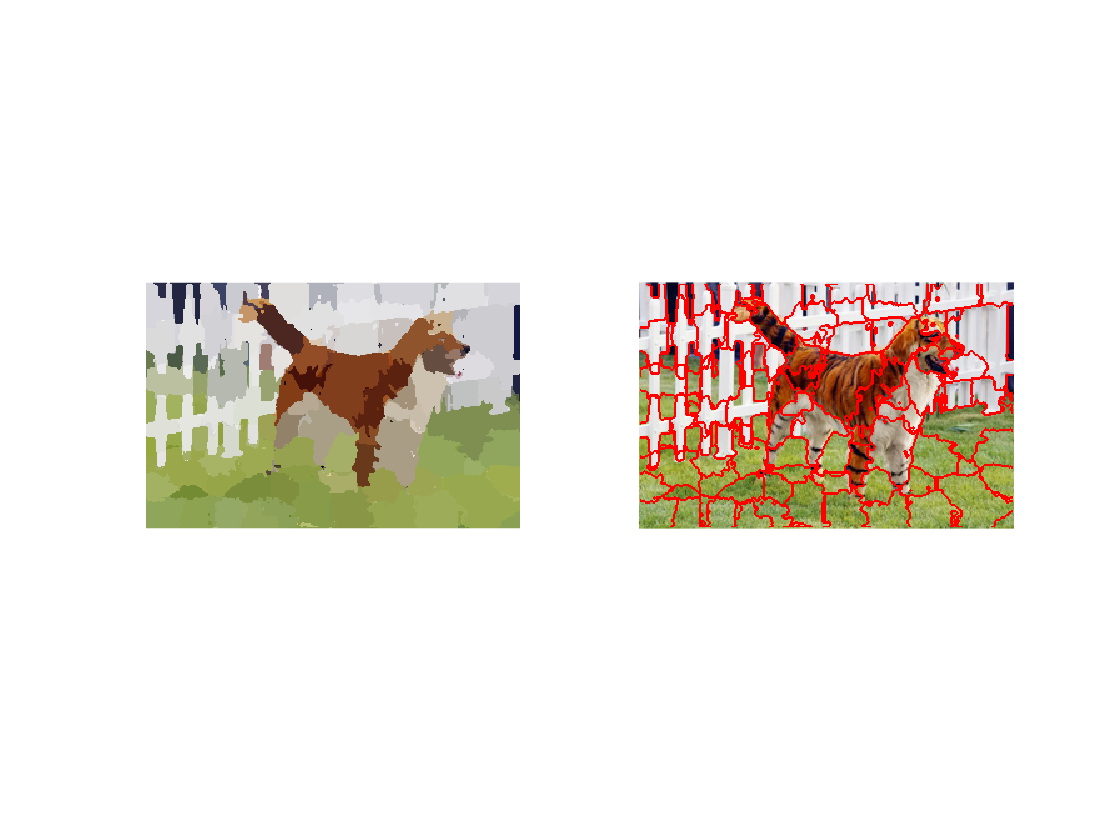

Inew = mean_segments(Iback, segm);
Ibounds = overlay_bounds(Iback, segm);
%imwrite(Inew,'result/meanshift1.png')
%imwrite(I,'result/meanshift2.png')
subplot(1,2,1); imshow(Inew);
subplot(1,2,2); imshow(Ibounds);

% Q7
close all;
colour_bandwidth = 20.0; % color bandwidth
radius = 30;              % maximum neighbourhood distance
ncuts_thresh = 0.5;      % cutting threshold
min_area = 100;          % minimum area of segment
max_depth = 4;           % maximum splitting depth
scale_factor = 0.4;      % image downscale factor
image_sigma = 2.0;       % image preblurring scale

I = imread('tiger1.jpg');
I = imresize(I, scale_factor);
Iback = I;
d = 2*ceil(image_sigma*2) + 1;
h = fspecial('gaussian', [d d], image_sigma);
I = imfilter(I, h);

segm = norm_cuts_segm(I, colour_bandwidth, radius, ncuts_thresh, min_area, max_depth);

Compute affinity matrix...
Elapsed time is 16.505748 seconds.
Solve eigenvalue problems to find partitions...
Cutting ncut=0.029 sizes=(16934,16658)
Cutting ncut=0.044 sizes=(13134,3800)
Cutting ncut=0.082 sizes=(11572,1562)
Cutting ncut=0.172 sizes=(11498,74)
Cutting ncut=0.203 sizes=(596,966)
Cutting ncut=0.172 sizes=(130,466)
Cutting ncut=0.347 sizes=(589,377)
Cutting ncut=0.056 sizes=(641,3159)
Cutting ncut=0.276 sizes=(572,69)
Cutting ncut=0.213 sizes=(1821,1338)
Cutting ncut=0.122 sizes=(1420,401)
Cutting ncut=0.266 sizes=(771,567)
Cutting ncut=0.031 sizes=(8098,8560)
Cutting ncut=0.136 sizes=(3893,4205)
Cutting ncut=0.084 sizes=(2673,1220)
Cutting ncut=0.230 sizes=(2527,146)
Cutting ncut=0.329 sizes=(571,649)
Cutting ncut=0.200 sizes=(2442,1763)
Cutting ncut=0.201 sizes=(775,1667)
Cutting ncut=0.307 sizes=(637,1126)
Cutting ncut=0.054 sizes=(5161,3399)
Cutting ncut=0.222 sizes=(871,4290)
Cutting ncut=0.415 sizes=(415,456)
Cutting ncut=0.214 sizes=(556,3734)
Cutting ncut=0.308 si

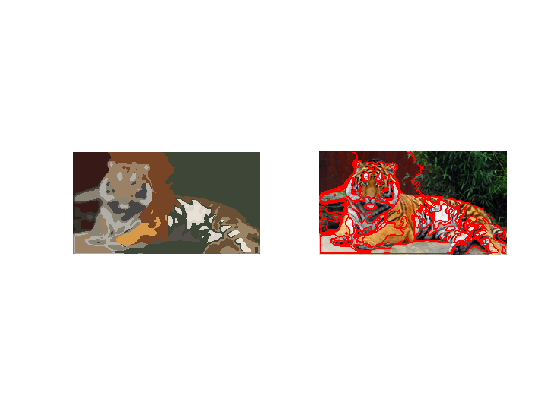

Inew = mean_segments(Iback, segm);
Ibounds = overlay_bounds(Iback, segm);
%imwrite(Inew,'result/normcuts1.png')
%imwrite(I,'result/normcuts2.png')
subplot(1,2,1); imshow(Inew);
subplot(1,2,2); imshow(Ibounds);

scale_factor = 0.5;          % image downscale factor
area = [ 80, 110, 570, 300 ] % image region to train foreground with

area =     80   110   570   300


K = 16;                      % number of mixture components
alpha = 8.0;                 % maximum edge cost
sigma = 10.0;                % edge cost decay factor

I = imread('tiger1.jpg');
I = imresize(I, scale_factor);
Iback = I;
area = int16(area*scale_factor);
[ segm, prior ] = graphcut_segm(I, area, K, alpha, sigma);

Find Gaussian mixture models...
       23616



       28744



Elapsed time is 0.931274 seconds.
Find minimum cut...
number of iterations = 100. 

Elapsed time is 1.236603 seconds.
Find Gaussian mixture models...
     0



Error using randperm
K must be less than or equal to N.

Error in kmeans_segm (line 18)
centers = pixels(randperm(num_pixels,K),:);

Error in mixture_prob (line 15)
[segm, centers] = kmeans_segm(pixels, K, L);

Error in 


Inew = mean_segments(Iback, segm);
Ibounds = overlay_bounds(Iback, segm);
% imwrite(Inew,'result/graphcut1.png')
% imwrite(I,'result/graphcut2.png')
% imwrite(prior,'result/graphcut3.png')
subplot(2,2,1); imshow(Inew);
subplot(2,2,2); imshow(Ibounds);
subplot(2,2,3); imshow(prior);
